# MidTerm

# Name - Vinay Patil

# Net Id - vpatil3

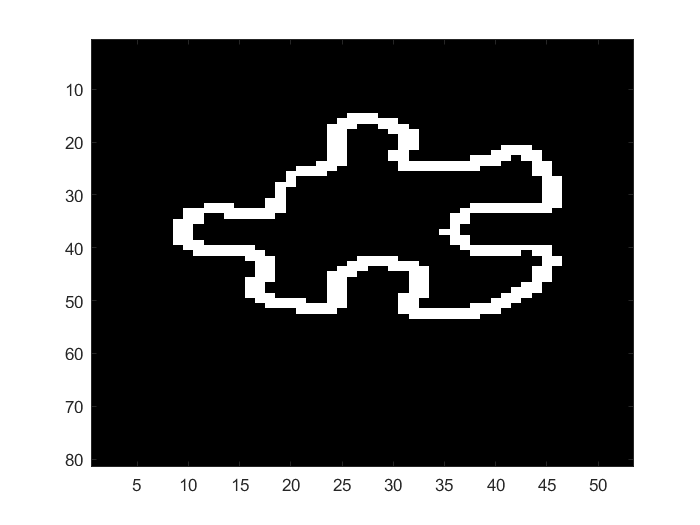

%Preprocessing steps for orange_piece.jpg
orangePiece = double(imread("orange_piece.jpg"));
%Resize orangePiece to lower the resolution by a factor of 5
newOrangePieceRows = ceil(size(orangePiece,1)/5);
newOrangePieceCols = ceil(size(orangePiece,2)/5);
orangePiece = imresize(orangePiece,[newOrangePieceRows newOrangePieceCols]);
%Changing to grayScale
orangePiece = 0.2989*orangePiece(:,:,1)+0.5870*orangePiece(:,:,2)+0.1140*orangePiece(:,:,3);
%Removing noise from the image
orangePieceGray = medfilt2(orangePiece);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(orangePieceGray, ksx, 'same');
gy = conv2(orangePieceGray, ksy, 'same');
orangePiece = sqrt(gx.^2 + gy.^2);
orangePiece = orangePiece>330;
figure
imagesc(orangePiece);

%Finding x_c and y_c
[x_coord,y_coord] = find(orangePiece >0);
x_c = round(mean(x_coord));
y_c = round(mean(y_coord));

%Finding angles for orange_piece.jpg edge points
dir_grad_piece = atan2(gy,gx);
dir_grad_piece(orangePiece==0) = 0;
dir_grad_piece = round(dir_grad_piece*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_piece);
unique_angles = unique_angles(unique_angles~=0);

%Constructing R-Table
R_Table = struct;
count = 1;
for phi_degree=unique_angles'
    [x,y] = find(dir_grad_piece==phi_degree);
    x_prime = x_c - x;
    y_prime = y_c - y;
    r = sqrt(x_prime.^2 + y_prime.^2);
    alpha_rad = atan2(y_prime,x_prime);
    R_Table(count).phi = phi_degree;
    R_Table(count).alpha = round(alpha_rad*180/pi)';
    R_Table(count).length = r';
    count = count + 1;
end

struct2table(R_Table);


%Preprocessing steps for main.jpg
colormap('gray')

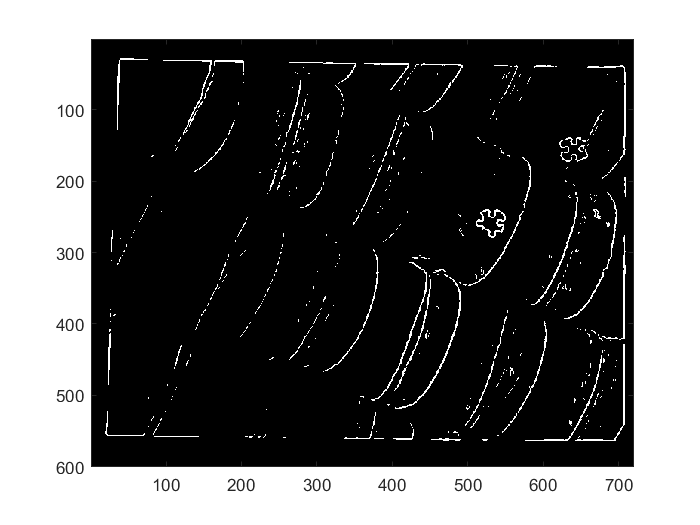

main = double(imread("main.jpg"));
%Resize main to lower the resolution by a factor of 5
newMainRows = ceil(size(main,1)/5);
newMainCols = ceil(size(main,2)/5);
main = imresize(main,[newMainRows newMainCols]);
%Changing to grayScale
main = 0.2989*main(:,:,1)+0.5870*main(:,:,2)+0.1140*main(:,:,3);
%Removing noise from the image
mainGray = medfilt2(main);
%Detecting edges and binarizing
ksx = reshape([-1 -2 -1 0 0 0 1 2 1], 3, 3 );
ksy = ksx';
gx = conv2(mainGray, ksx, 'same');
gy = conv2(mainGray, ksy, 'same');
main = sqrt(gx.^2 + gy.^2);
main = main>250;
imagesc(main);

## 1) Generalized Hough Transform

ans = 205×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -180    [       120]    [   13.8924]
    -177    [1×3 double]    [1×3 double]
    -176    [        16]    [   17.7200]
    -175    [        25]    [   14.3178]
    -174    [1×2 double]    [1×2 double]
    -173    [1×3 double]    [1×3 double]
    -170    [        67]    [        13]
    -168    [1×3 double]    [1×3 double]
    -167    [1×2 double]    [1×2 double]
    -166    [1×2 double]    [1×2 double]
    -164    [1×2 double]    [1×2 double]
    -163    [1×3 double]    [1×3 double]
    -162    [       130]    [   15.6205]
    -161    [1×2 double]    [1×2 double]
    -160    [1×3 double]    [1×3 double]
    -159    [       128]    [   17.8045]


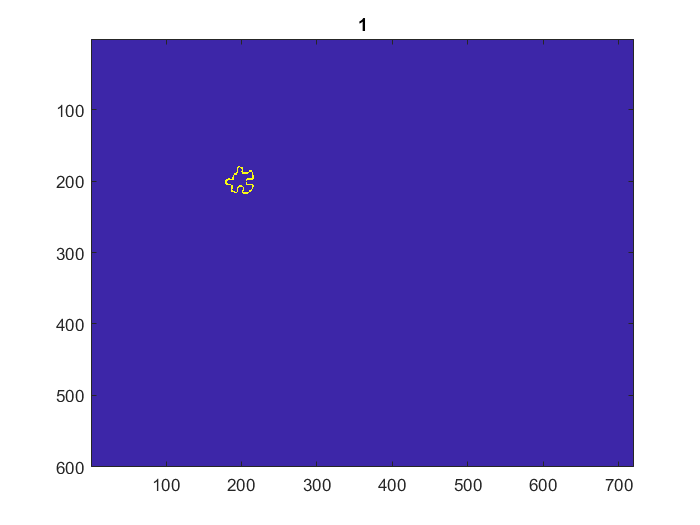

ans = 205×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -135    [       165]    [   13.8924]
    -132    [1×3 double]    [1×3 double]
    -131    [        61]    [   17.7200]
    -130    [        70]    [   14.3178]
    -129    [1×2 double]    [1×2 double]
    -128    [1×3 double]    [1×3 double]
    -125    [       112]    [        13]
    -123    [1×3 double]    [1×3 double]
    -122    [1×2 double]    [1×2 double]
    -121    [1×2 double]    [1×2 double]
    -119    [1×2 double]    [1×2 double]
    -118    [1×3 double]    [1×3 double]
    -117    [       175]    [   15.6205]
    -116    [1×2 double]    [1×2 double]
    -115    [1×3 double]    [1×3 double]
    -114    [       173]    [   17.8045]


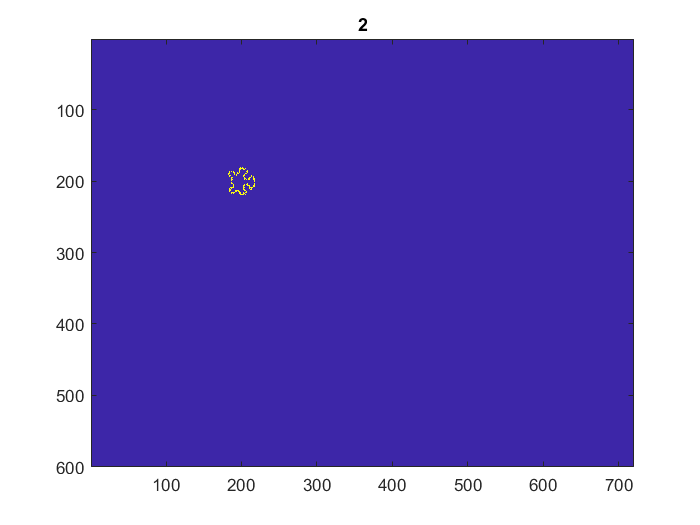

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

    -90    [       210]    [   13.8924]
    -87    [1×3 double]    [1×3 double]
    -86    [       106]    [   17.7200]
    -85    [       115]    [   14.3178]
    -84    [1×2 double]    [1×2 double]
    -83    [1×3 double]    [1×3 double]
    -80    [       157]    [        13]
    -78    [1×3 double]    [1×3 double]
    -77    [1×2 double]    [1×2 double]
    -76    [1×2 double]    [1×2 double]
    -74    [1×2 double]    [1×2 double]
    -73    [1×3 double]    [1×3 double]
    -72    [       220]    [   15.6205]
    -71    [1×2 double]    [1×2 double]
    -70    [1×3 double]    [1×3 double]
    -69    [       218]    [   17.8045]


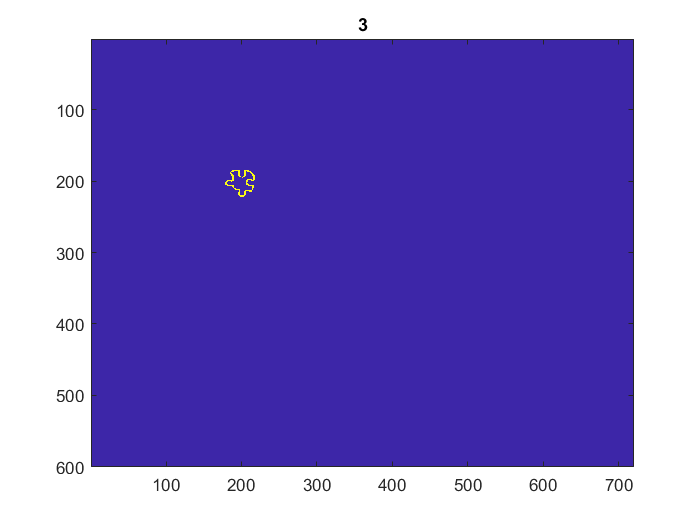

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

    -45    [       255]    [   13.8924]
    -42    [1×3 double]    [1×3 double]
    -41    [       151]    [   17.7200]
    -40    [       160]    [   14.3178]
    -39    [1×2 double]    [1×2 double]
    -38    [1×3 double]    [1×3 double]
    -35    [       202]    [        13]
    -33    [1×3 double]    [1×3 double]
    -32    [1×2 double]    [1×2 double]
    -31    [1×2 double]    [1×2 double]
    -29    [1×2 double]    [1×2 double]
    -28    [1×3 double]    [1×3 double]
    -27    [       265]    [   15.6205]
    -26    [1×2 double]    [1×2 double]
    -25    [1×3 double]    [1×3 double]
    -24    [       263]    [   17.8045]


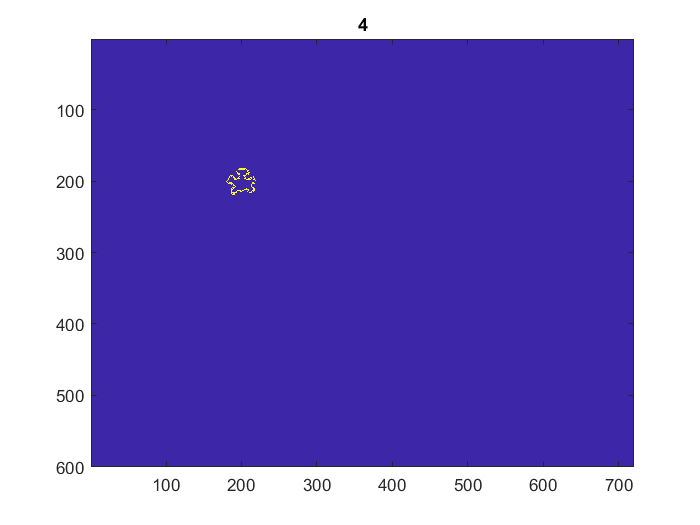

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

     0     [       300]    [   13.8924]
     3     [1×3 double]    [1×3 double]
     4     [       196]    [   17.7200]
     5     [       205]    [   14.3178]
     6     [1×2 double]    [1×2 double]
     7     [1×3 double]    [1×3 double]
    10     [       247]    [        13]
    12     [1×3 double]    [1×3 double]
    13     [1×2 double]    [1×2 double]
    14     [1×2 double]    [1×2 double]
    16     [1×2 double]    [1×2 double]
    17     [1×3 double]    [1×3 double]
    18     [       310]    [   15.6205]
    19     [1×2 double]    [1×2 double]
    20     [1×3 double]    [1×3 double]
    21     [       308]    [   17.8045]


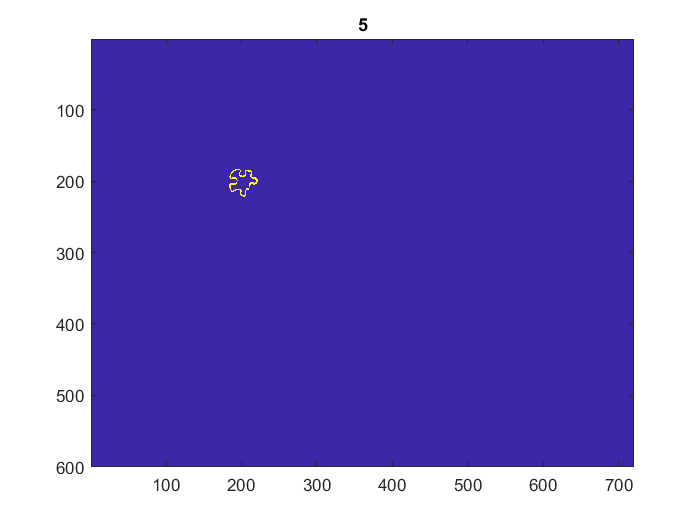

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

    45     [       345]    [   13.8924]
    48     [1×3 double]    [1×3 double]
    49     [       241]    [   17.7200]
    50     [       250]    [   14.3178]
    51     [1×2 double]    [1×2 double]
    52     [1×3 double]    [1×3 double]
    55     [       292]    [        13]
    57     [1×3 double]    [1×3 double]
    58     [1×2 double]    [1×2 double]
    59     [1×2 double]    [1×2 double]
    61     [1×2 double]    [1×2 double]
    62     [1×3 double]    [1×3 double]
    63     [       355]    [   15.6205]
    64     [1×2 double]    [1×2 double]
    65     [1×3 double]    [1×3 double]
    66     [       353]    [   17.8045]


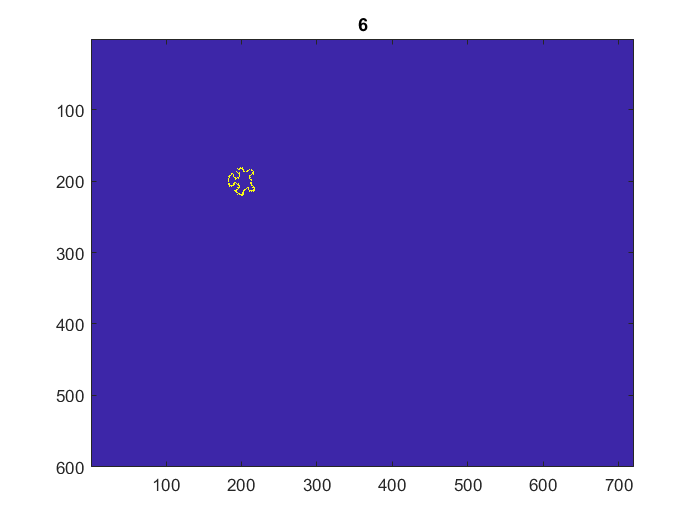

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

     90    [       390]    [   13.8924]
     93    [1×3 double]    [1×3 double]
     94    [       286]    [   17.7200]
     95    [       295]    [   14.3178]
     96    [1×2 double]    [1×2 double]
     97    [1×3 double]    [1×3 double]
    100    [       337]    [        13]
    102    [1×3 double]    [1×3 double]
    103    [1×2 double]    [1×2 double]
    104    [1×2 double]    [1×2 double]
    106    [1×2 double]    [1×2 double]
    107    [1×3 double]    [1×3 double]
    108    [       400]    [   15.6205]
    109    [1×2 double]    [1×2 double]
    110    [1×3 double]    [1×3 double]
    111    [       398]    [   17.8045]


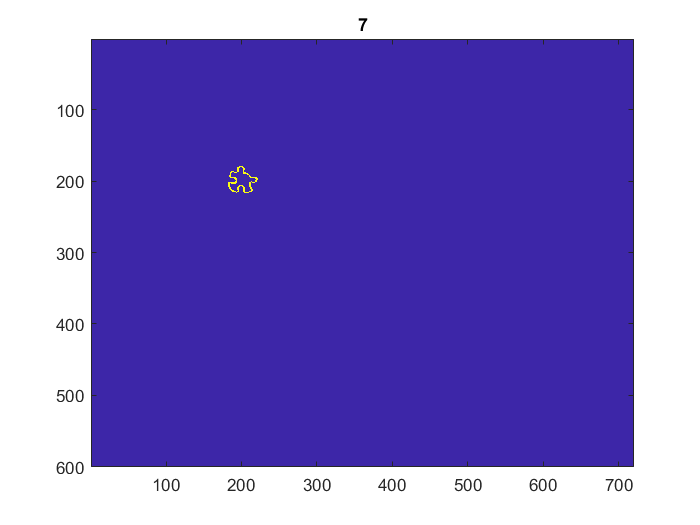

ans = 205×3 table
    phi       alpha           length   
    ___    ____________    ____________

    135    [       435]    [   13.8924]
    138    [1×3 double]    [1×3 double]
    139    [       331]    [   17.7200]
    140    [       340]    [   14.3178]
    141    [1×2 double]    [1×2 double]
    142    [1×3 double]    [1×3 double]
    145    [       382]    [        13]
    147    [1×3 double]    [1×3 double]
    148    [1×2 double]    [1×2 double]
    149    [1×2 double]    [1×2 double]
    151    [1×2 double]    [1×2 double]
    152    [1×3 double]    [1×3 double]
    153    [       445]    [   15.6205]
    154    [1×2 double]    [1×2 double]
    155    [1×3 double]    [1×3 double]
    156    [       443]    [   17.8045]


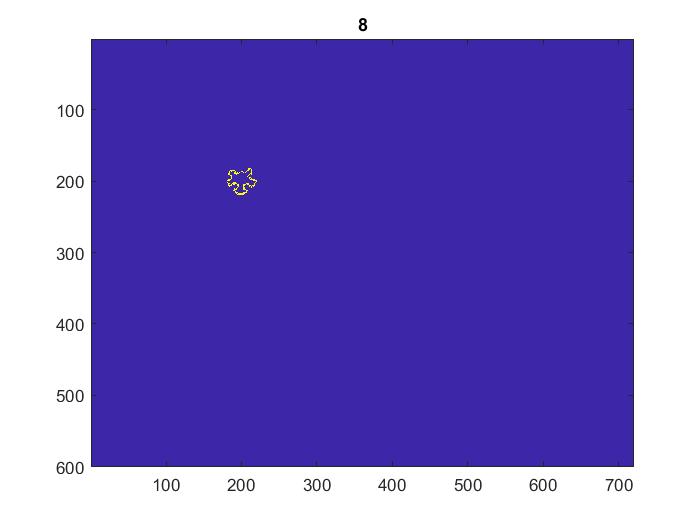

ans = 205×3 table
    phi        alpha           length   
    ____    ____________    ____________

     180    [       480]    [   13.8924]
    -177    [1×3 double]    [1×3 double]
    -176    [       376]    [   17.7200]
    -175    [       385]    [   14.3178]
    -174    [1×2 double]    [1×2 double]
    -173    [1×3 double]    [1×3 double]
    -170    [       427]    [        13]
    -168    [1×3 double]    [1×3 double]
    -167    [1×2 double]    [1×2 double]
    -166    [1×2 double]    [1×2 double]
    -164    [1×2 double]    [1×2 double]
    -163    [1×3 double]    [1×3 double]
    -162    [       490]    [   15.6205]
    -161    [1×2 double]    [1×2 double]
    -160    [1×3 double]    [1×3 double]
    -159    [       488]    [   17.8045]


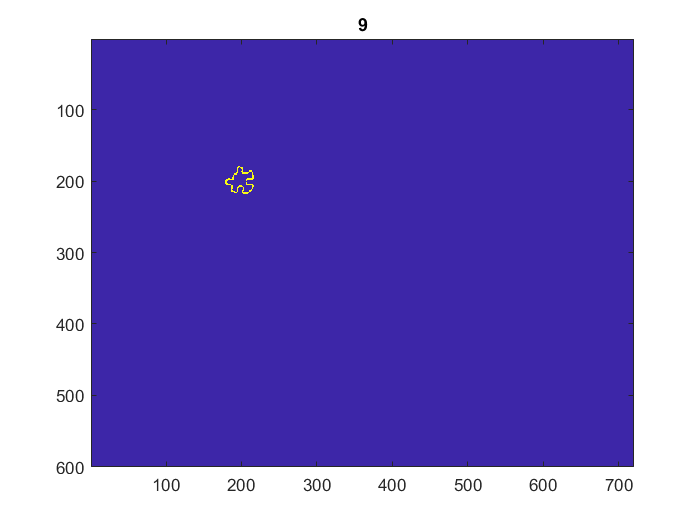

ans = 205×3 table
    phi        alpha           length   
    ____    ____________    ____________

    -135    [       525]    [   13.8924]
    -132    [1×3 double]    [1×3 double]
    -131    [       421]    [   17.7200]
    -130    [       430]    [   14.3178]
    -129    [1×2 double]    [1×2 double]
    -128    [1×3 double]    [1×3 double]
    -125    [       472]    [        13]
    -123    [1×3 double]    [1×3 double]
    -122    [1×2 double]    [1×2 double]
    -121    [1×2 double]    [1×2 double]
    -119    [1×2 double]    [1×2 double]
    -118    [1×3 double]    [1×3 double]
    -117    [       535]    [   15.6205]
    -116    [1×2 double]    [1×2 double]
    -115    [1×3 double]    [1×3 double]
    -114    [       533]    [   17.8045]


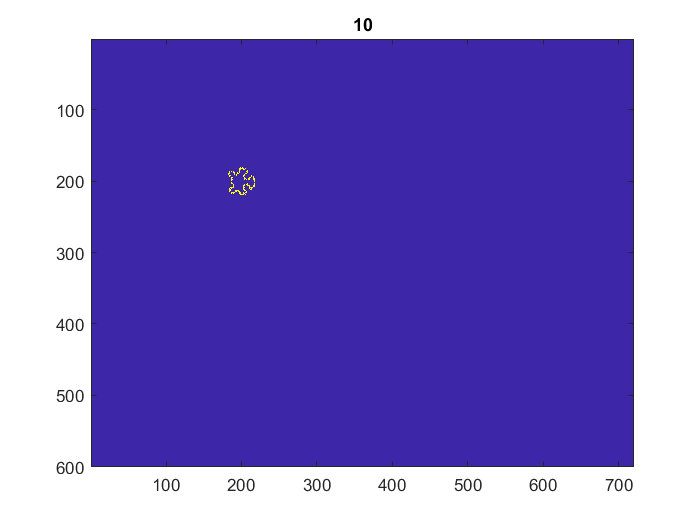

%Finding angles for main.jpg edge points
dir_grad_main = atan2(gy,gx);
dir_grad_main(main==0) = 0;
dir_grad_main = round(dir_grad_main*180/pi);

%Getting unique angles and ignoring non-edge angles i.e 0
unique_angles = unique(dir_grad_main);
unique_angles = unique_angles(unique_angles~=0);

%Building accumulation matrix
rows = size(main,1);
cols = size(main,2);
no_of_rotations = 360/45;
acc_matrix = zeros(rows,cols,no_of_rotations);
R_Table_New = R_Table;

for rot=0:no_of_rotations-1
    if(rot>0)
        R_Table_New = rotatePhi(R_Table,rot);
    end
    
    for phi_degree=unique_angles'
        [x,y] = find(dir_grad_main==phi_degree);
        matchedLogical = [R_Table_New.phi]==phi_degree;
        
        if sum(matchedLogical)==1
            match = R_Table_New(matchedLogical);
            nums = length(match.alpha); % The length vector will also be of same size, can consider either here
            for i=1:nums
                x_candidate = round(x + match.length(i)*cos(match.alpha(i)*pi/180));
                y_candidate = round(y + match.length(i)*sin(match.alpha(i)*pi/180));
                
                %Getting valid coordintes for accumulator matrix
                coord_x = x_candidate<=rows & x_candidate>0;
                coord_y = y_candidate<=cols & y_candidate>0;
                valids = coord_x & coord_y;
                x_candidate = x_candidate(valids);
                y_candidate = y_candidate(valids);
                
                count = sum(valids);
                for j=1:count
                    acc_matrix(x_candidate(j),y_candidate(j),rot+1) = acc_matrix(x_candidate(j),y_candidate(j),rot+1) + 1;
                end
            end
        end
    end
end

%Finding optimal accumulation matrix
max_val = 0;
x_cen = 200;
y_cen = 200;
for rot_index=1:10
    
    generated_shape = zeros(rows,cols);
    table = rotatePhi(R_Table,rot_index-1);
    struct2table(table)
    
    for k=1:length(table)
        nums = length(table(k).alpha);
        for i=1:nums
            xloop = round(x_cen-(table(k).length(i)*cos(table(k).alpha(i)*pi/180)));
            yloop = round(y_cen-(table(k).length(i)*sin(table(k).alpha(i)*pi/180)));
            if xloop>0 && yloop>0 && xloop<=rows && yloop<=cols
                generated_shape(xloop,yloop) = 1;
            end
        end
    end
    
    figure
    imagesc(generated_shape);
    title(rot_index);
end

%Function to rotate the R-Table

function new_table = rotatePhi(table,rot)
for k=1:length(table)
    temp = table(k).phi + rot*45;
    
    if(temp>180)
        x = mod(temp,360);
        if(x>180)
            x = -180 + mod(x,180);
        end
        temp = x;
    end
    table(k).phi = temp;
    table(k).alpha = table(k).alpha + rot*45;
end
new_table = table;
end
